# Midterm November 16, 2018

## Exercise 1

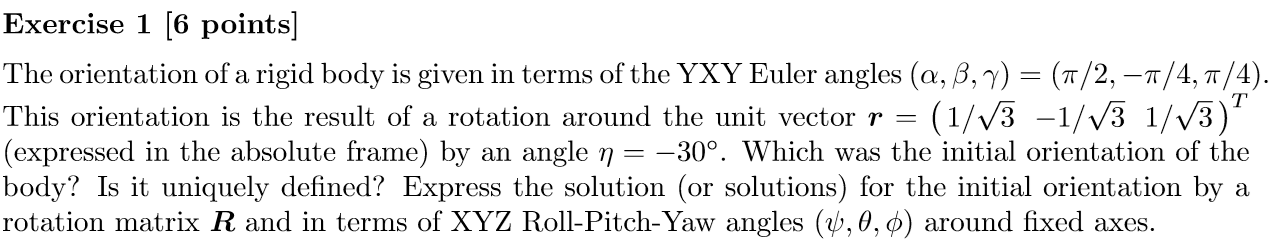

syms alpha beta gamma
[Rx Ry Rz] = getEulerRotationMatrices()

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(a_{1}\right) & -\sin\left(a_{1}\right)\\ 0 & \sin\left(a_{1}\right) & \cos\left(a_{1}\right) \end{array}\right)$$

$$Ry = \left(\begin{array}{ccc} \cos\left(a_{2}\right) & 0 & \sin\left(a_{2}\right)\\ 0 & 1 & 0\\ -\sin\left(a_{2}\right) & 0 & \cos\left(a_{2}\right) \end{array}\right)$$

$$Rz = \left(\begin{array}{ccc} \cos\left(a_{3}\right) & -\sin\left(a_{3}\right) & 0\\ \sin\left(a_{3}\right) & \cos\left(a_{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


% Eugler angle matrices are multipled in forward order. 
% Not reversed, like roll-pitch-yaw angles
RYXY = simplify(Rx*Ry*Rx)

$$RYXY = \begin{array}{l} \left(\begin{array}{ccc} \cos\left(a_{2}\right) & \sin\left(a_{1}\right)\,\sin\left(a_{2}\right) & \cos\left(a_{1}\right)\,\sin\left(a_{2}\right)\\ \sin\left(a_{1}\right)\,\sin\left(a_{2}\right) & {\cos\left(a_{1}\right)}^{2}-\cos\left(a_{2}\right)\,{\sin\left(a_{1}\right)}^{2} & -\sigma_{1}\\ -\cos\left(a_{1}\right)\,\sin\left(a_{2}\right) & \sigma_{1} & {\cos\left(a_{1}\right)}^{2}+{\cos\left(a_{1}\right)}^{2}\,\cos\left(a_{2}\right)-1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(2\,a_{1}\right)\,\left(\cos\left(a_{2}\right)+1\right)}{2} \end{array}$$

[R_total, R_set] = getRotMatProduct('YXY',0,[alpha, beta, gamma])

$$R\_total = \left(\begin{array}{ccc} \cos\left(\alpha \right)\,\cos\left(\gamma \right)-\cos\left(\beta \right)\,\sin\left(\alpha \right)\,\sin\left(\gamma \right) & \sin\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\beta \right)\,\cos\left(\gamma \right)\,\sin\left(\alpha \right)\\ \sin\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\beta \right) & -\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ -\cos\left(\gamma \right)\,\sin\left(\alpha \right)-\cos\left(\alpha \right)\,\cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\sin\left(\beta \right) & \cos\left(\alpha \right)\,\cos\left(\beta \right)\,\cos\left(\gamma \right)-\sin\left(\alpha \right)\,\sin\left(\gamma \right) \end{array}\right)$$

R_set = 3×1 cell array
    {3×3 sym}
    {3×3 sym}
    {3×3 sym}


angles = [pi/2, -pi/4, pi/4]

angles =     1.5708   -0.7854    0.7854


% substitute the value of the angles
R_0_f = subs(R_total,[alpha, beta, gamma], angles)

$$R\_0\_f = \left(\begin{array}{ccc} -\frac{1}{2} & -\frac{\sqrt{2}}{2} & \frac{1}{2}\\ -\frac{1}{2} & \frac{\sqrt{2}}{2} & \frac{1}{2}\\ -\frac{\sqrt{2}}{2} & 0 & -\frac{\sqrt{2}}{2} \end{array}\right)$$

% Calculate the rotation of the body around the unit vector
unit_vector = [1/sqrt(3), -1/sqrt(3) 1/sqrt(3)].'

unit_vector =     0.5774
   -0.5774
    0.5774


eta = deg2rad(-30)

eta = -0.5236

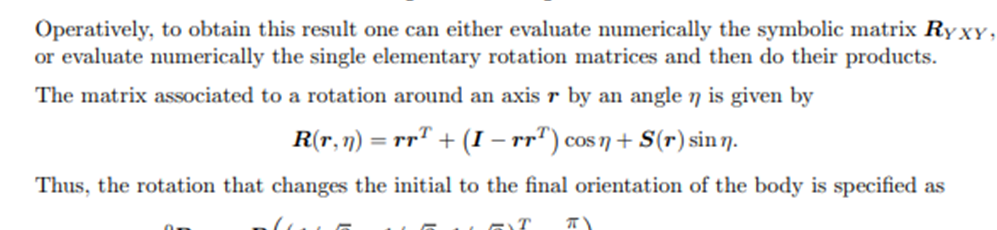.

R_0_if = getRotAroundVector(unit_vector,eta)

R_0_if =     0.9107    0.2440    0.3333
   -0.3333    0.9107    0.2440
   -0.2440   -0.3333    0.9107


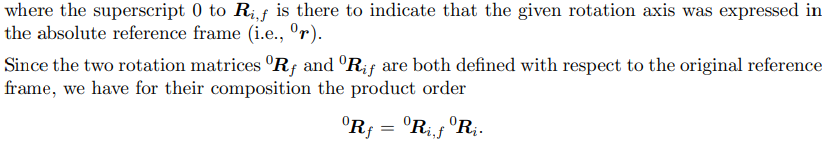

R_0_i = R_0_if.'*R_0_f; % Initial position expressed in absolute frame
eval(R_0_i)

ans =    -0.1161   -0.8797    0.4612
   -0.3416    0.4714    0.8131
   -0.9326   -0.0632   -0.3553


Get the Roll_Picth_Yaw matrix equivalent. Inverse problem

syms psi theta phi
[R_total_rpy, R_set_rpy] = getRotMatProduct('XYZ',1,[psi theta phi])

$$R\_total\_rpy = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

R_set_rpy = 3×1 cell array
    {3×3 sym}
    {3×3 sym}
    {3×3 sym}


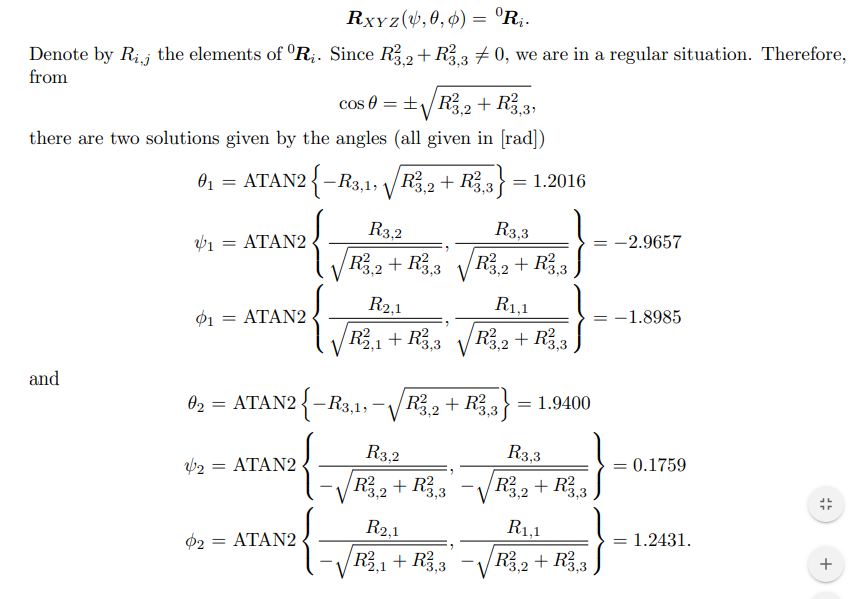

angs = solve(R_total_rpy == R_0_i)

angs = struct with fields:
      phi: [0×1 sym]
      psi: [0×1 sym]
    theta: [0×1 sym]


% Peter Corke function to get the Roll-Pitch-Yaw angles
tr2rpy(R_0_i,'zyx') %inverse order in regression

ans =    -2.9657    1.2016   -1.8985


## Exercise 2

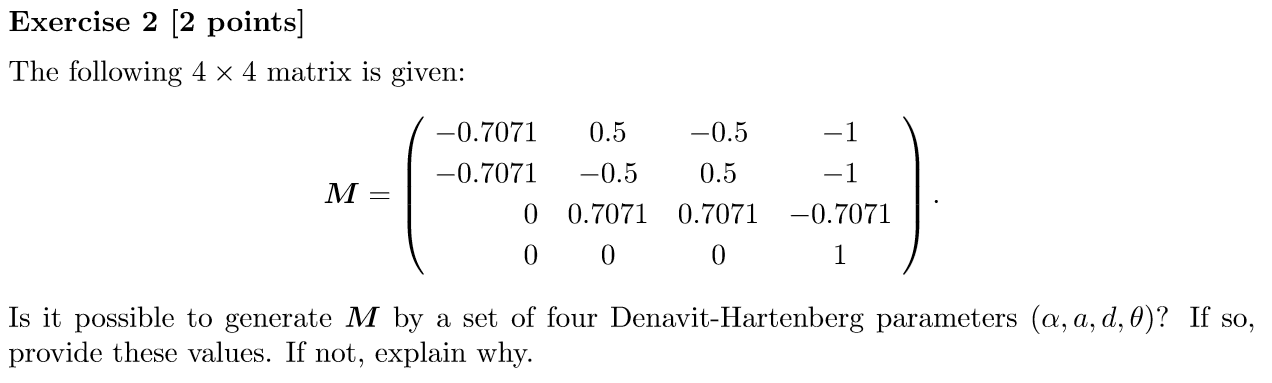

The last row is composed by three zeros and a 1, which are the correct usual values. The vector in the fourth column can have any value, since it's a possition. The upper left 3x3 matrix must be a rotational matrix, that is, orthonormal matrix: The determinant must be one, it's transpose is the same inverse.

Check orthonormality of the rotation martrix.

M = [-0.7071 0.5 -0.5 -1;
     -0.7071 -0.5 0.5 -1;
      0 0.7071 0.7071 -0.7071;
      0 0 0 1]

M =    -0.7071    0.5000   -0.5000   -1.0000
   -0.7071   -0.5000    0.5000   -1.0000
         0    0.7071    0.7071   -0.7071
         0         0         0    1.0000


  Mpi1=(1/pi)*M

Mpi1 =    -0.2251    0.1592   -0.1592   -0.3183
   -0.2251   -0.1592    0.1592   -0.3183
         0    0.2251    0.2251   -0.2251
         0         0         0    0.3183


R = M(1:3,1:3)

R =    -0.7071    0.5000   -0.5000
   -0.7071   -0.5000    0.5000
         0    0.7071    0.7071


Es necesario comprobar que M es homgeno y ortogonal el determinante debe ser +1

round(inv(R),4)==round(R.',4) % since all of them are ones, it meets the req.

ans = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


det(R)

ans = 1.0000

det(inv(R))

ans = 1.0000

syms alpha a d theta m07 m05;
Mtd=[-m07 m05 -m05 -1;-m07 -m05 m05 -1;0 m07 m07 -m07;0 0 0 1]

$$Mtd = \left(\begin{array}{cccc} -m_{07} & m_{05} & -m_{05} & -1\\ -m_{07} & -m_{05} & m_{05} & -1\\ 0 & m_{07} & m_{07} & -m_{07}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DHParams = [alpha a d theta]

$$DHParams = \left(\begin{array}{cccc} \alpha & a & d & \theta \end{array}\right)$$


DHMatrix = getDHSymMatrix() % Generic rotation translation matrix

$$DHMatrix = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right) & a\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right) & a\,\sin\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$


DHMatrix == Mtd

$$ans = \left(\begin{array}{cccc} \cos\left(\theta \right)=-m_{07} & -\cos\left(\alpha \right)\,\sin\left(\theta \right)=m_{05} & \sin\left(\alpha \right)\,\sin\left(\theta \right)=-m_{05} & a\,\cos\left(\theta \right)=-1\\ \sin\left(\theta \right)=-m_{07} & \cos\left(\alpha \right)\,\cos\left(\theta \right)=-m_{05} & -\sin\left(\alpha \right)\,\cos\left(\theta \right)=m_{05} & a\,\sin\left(\theta \right)=-1\\ 0=0 & \sin\left(\alpha \right)=m_{07} & \cos\left(\alpha \right)=m_{07} & d=-m_{07}\\ 0=0 & 0=0 & 0=0 & 1=1 \end{array}\right)$$

rd=solve(DHMatrix == Mtd)

rd = struct with fields:
        a: [2×1 sym]
    alpha: [2×1 sym]
        d: [2×1 sym]
      m05: [2×1 sym]
      m07: [2×1 sym]
    theta: [2×1 sym]


%[alpha_m a_m d_m theta_m ] = solve(DHMatrix == Mtd, DHParams)
M2 = subs(DHMatrix, DHParams, [pi/4,sqrt(2), -sqrt(2)/2,-3*pi/4])

$$M2 = \left(\begin{array}{cccc} -\frac{\sqrt{2}}{2} & \frac{1}{2} & -\frac{1}{2} & -1\\ -\frac{\sqrt{2}}{2} & -\frac{1}{2} & \frac{1}{2} & -1\\ 0 & \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

eval(M2)

ans =    -0.7071    0.5000   -0.5000   -1.0000
   -0.7071   -0.5000    0.5000   -1.0000
         0    0.7071    0.7071   -0.7071
         0         0         0    1.0000



%Cannot find the answer by 'solve' because the values are not exact.

dh = [-pi/2 220 346 0;
       pi/2  0  140 0]

dh =    -1.5708  220.0000  346.0000         0
    1.5708         0  140.0000         0


TB0 = getTransformationMatrix(dh, 'alpha')

$$TB0 = \left(\begin{array}{cccc} 1 & 0 & 0 & 220\\ 0 & 1 & 0 & 140\\ 0 & 0 & 1 & 346\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Rsym = DHMatrix(1:3,1:3)

$$Rsym = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

tr2rpy(R)

ans =     0.7854         0   -2.3562


## Exercise 3

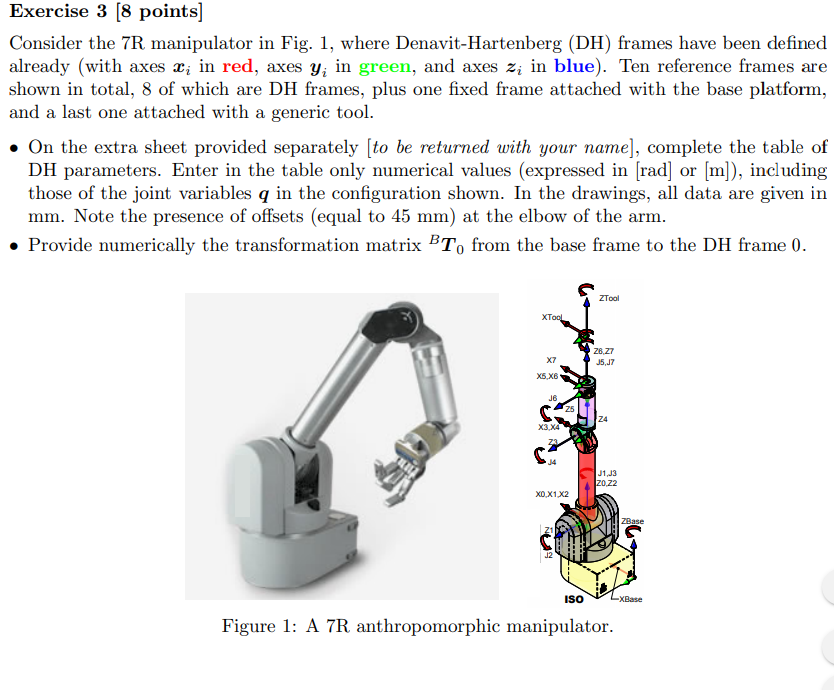

clear all, close all, clc
a3=45/1000

a3 = 0.0450

a4=-a3

a4 = -0.0450

d3=550/1000

d3 = 0.5500

d5=300/1000

d5 = 0.3000

d7=60/1000

d7 = 0.0600

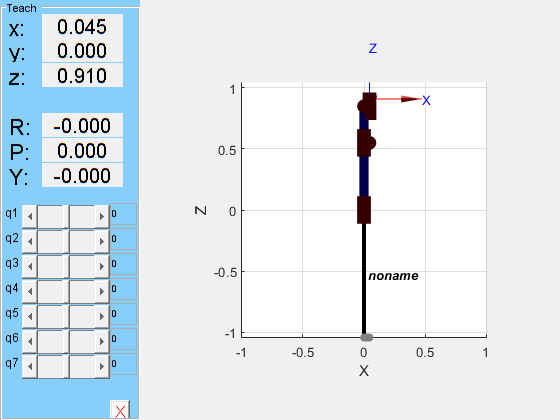

% De Luca's approach
links = [
    Revolute('alpha', -pi/2, 'a', 0 ,'d', 0);
    Revolute('alpha',  pi/2, 'a', 0 ,'d', 0);
    Revolute('alpha', -pi/2, 'a', a3 ,'d', d3);
    Revolute('alpha',  pi/2, 'a', a4 ,'d',0);
    Revolute('alpha', -pi/2, 'a', 0 ,'d', d5);
    Revolute('alpha',  pi/2, 'a', a3 ,'d', 0);
    Revolute('alpha',    0 , 'a', 0 ,'d', d7);




%     Revolute('a', len1, 'alpha', 0 ,'d', 0);
    ];
c600 = SerialLink(links);
c600.teach([0 0 0 0 0 0 0],'view','x')

## Exercise 5

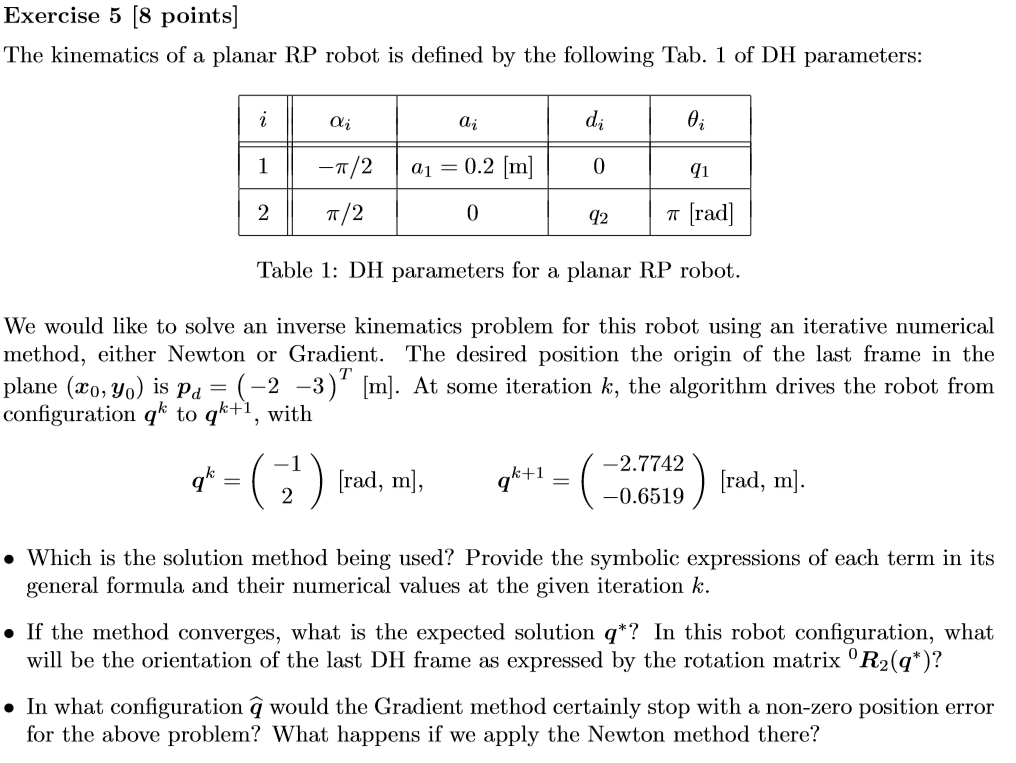

syms a1 q1 q2 
dhTable = [-pi/2, a1, 0, q1;
            pi/2, 0, q2, pi]

$$dhTable = \left(\begin{array}{cccc} -\frac{\pi }{2} & a_{1} & 0 & q_{1}\\ \frac{\pi }{2} & 0 & q_{2} & \pi \end{array}\right)$$


[T_total T_Partial] = getTransformationMatrix(dhTable, 'alpha')

$$T\_total = \left(\begin{array}{cccc} -\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & a_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & a_{1}\,\sin\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_Partial = 1×2 cell array
    {4×4 sym}    {4×4 sym}


p = T_total(1:2,4) % Planar position of the EE

$$p = \left(\begin{array}{c} a_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ a_{1}\,\sin\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right) \end{array}\right)$$

J = jacobian(p,[q1 q2])

$$J = \left(\begin{array}{cc} -a_{1}\,\sin\left(q_{1}\right)-q_{2}\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\\ a_{1}\,\cos\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) \end{array}\right)$$

L(1)=Link('alpha', -pi/2, 'a', 0.2, 'd', 0);
L(2)=Link('alpha', -pi/2, 'a', 0, 'theta', pi, 'qlim', [0,10]);
robot1 = SerialLink(L,'name','RPRobot')

 
robot1 = 
 
RPRobot:: 2 axis, RP, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|        0.2|    -1.5708|          0|
|  2|    3.14159|         q2|          0|    -1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


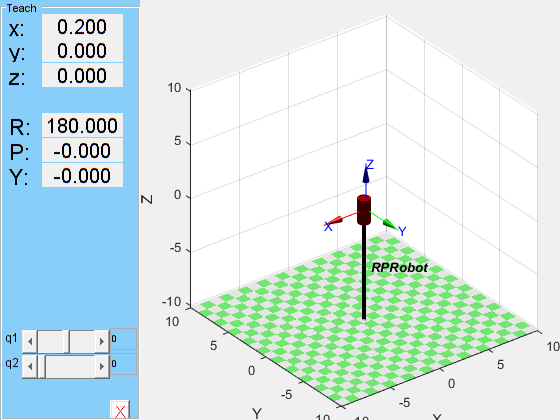

robot1.teach

pd = [-2, -3, 0].'

pd =     -2
    -3
     0


q = fminsearch( @(q) norm( robot1.fkine(q).t - pd ), [0 0] )

q =    -0.6435   -3.6001


%robot1.ikine(pd)

robot1.fkine([0,0]).t

ans =     0.2000
         0
         0
